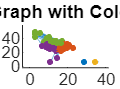

% Load the adjacency matrix of the control patient
A_cn = readmatrix('adjacency_matrix.csv', 'Delimiter', ',');

% Apply the Louvain algorithm
[Ci_cn, Q_cn] = community_louvain(A_cn);

% Create and visualize the graph with colored communities
G_cn = graph(A_cn);
plot_colored_graph(G_cn, Ci_cn, 'Control Patient Graph with Colored Communities');

fprintf('Control patient modularity: %f\n', Q_cn);

Control patient modularity: 0.194704


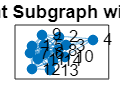


% Extract the DMN subgraph
subset_nodes = [22, 23, 24, 25, 34, 35, 36, 37, 38, 39, 64, 65, 66, 67];
A_sub_cn = A_cn(subset_nodes, subset_nodes);
G_sub_cn = graph(A_sub_cn);

% Visualize the subgraph
plot(G_sub_cn, 'Layout', 'force');
title('Control Patient Subgraph with DMN Nodes');

fprintf('1: Frontal_Sup_Medial_L \n2: Frontal_Sup_Medial_R\n3: Frontal_Med_Orb_L\n4: Frontal_Med_Orb_R\n5: Cingulum_Post_L\n6: Cingulum_Post_R\n7: Hippocampus_L\n8: Hippocampus_R\n9: ParaHippocampal_L\n10: ParaHippocampal_R\n11: Angular_L\n12: Angular_R\n13: Precuneus_L\n14: Precuneus_R\n');

1: Frontal_Sup_Medial_L 
2: Frontal_Sup_Medial_R
3: Frontal_Med_Orb_L
4: Frontal_Med_Orb_R
5: Cingulum_Post_L
6: Cingulum_Post_R
7: Hippocampus_L
8: Hippocampus_R
9: ParaHippocampal_L
10: ParaHippocampal_R
11: Angular_L
12: Angular_R
13: Precuneus_L
14: Precuneus_R


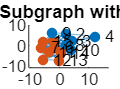


% Apply the Louvain algorithm to the DMN subgraph
[Ci_dmn_cn, Q_dmn_cn] = community_louvain(A_sub_cn);
plot_colored_graph(G_sub_cn, Ci_dmn_cn, 'Control Patient DMN Subgraph with Colored Communities');

fprintf('Control patient DMN subgraph modularity: %f\n', Q_dmn_cn);

Control patient DMN subgraph modularity: 0.067389


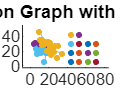


% Load the adjacency matrix of the patient with the condition
A_ad = readmatrix('adjacency_matrix_ad.csv', 'Delimiter', ',');

% Apply the Louvain algorithm
[Ci_ad, Q_ad] = community_louvain(A_ad);

% Create and visualize the graph with colored communities
G_ad = graph(A_ad);
plot_colored_graph(G_ad, Ci_ad, 'Patient with Condition Graph with Colored Communities');

fprintf('Patient with condition modularity: %f\n', Q_ad);

Patient with condition modularity: 0.268042


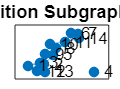


% Extract the DMN subgraph
A_sub_ad = A_ad(subset_nodes, subset_nodes);
G_sub_ad = graph(A_sub_ad);

% Visualize the subgraph
plot(G_sub_ad, 'Layout', 'force');
title('Patient with Condition Subgraph with DMN Nodes');

fprintf('1: Frontal_Sup_Medial_L \n2: Frontal_Sup_Medial_R\n3: Frontal_Med_Orb_L\n4: Frontal_Med_Orb_R\n5: Cingulum_Post_L\n6: Cingulum_Post_R\n7: Hippocampus_L\n8: Hippocampus_R\n9: ParaHippocampal_L\n10: ParaHippocampal_R\n11: Angular_L\n12: Angular_R\n13: Precuneus_L\n14: Precuneus_R\n');

1: Frontal_Sup_Medial_L 
2: Frontal_Sup_Medial_R
3: Frontal_Med_Orb_L
4: Frontal_Med_Orb_R
5: Cingulum_Post_L
6: Cingulum_Post_R
7: Hippocampus_L
8: Hippocampus_R
9: ParaHippocampal_L
10: ParaHippocampal_R
11: Angular_L
12: Angular_R
13: Precuneus_L
14: Precuneus_R


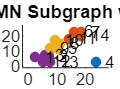


% Apply the Louvain algorithm to the DMN subgraph
[Ci_dmn_ad, Q_dmn_ad] = community_louvain(A_sub_ad);
plot_colored_graph(G_sub_ad, Ci_dmn_ad, 'Patient with Condition DMN Subgraph with Colored Communities');

fprintf('Patient with condition DMN subgraph modularity: %f\n', Q_dmn_ad);

Patient with condition DMN subgraph modularity: 0.460055



% Analysis and comparison
% Node centrality
centrality_cn = centrality(G_sub_cn, 'degree');
centrality_ad = centrality(G_sub_ad, 'degree');

% Internal and external connections
conn_cn = analyze_connections(A_sub_cn, Ci_dmn_cn);
conn_ad = analyze_connections(A_sub_ad, Ci_dmn_ad);

% Print comparison results
fprintf('Comparison between control patient and patient with condition:\n');

Comparison between control patient and patient with condition:


fprintf('- DMN modularity: control = %f, condition = %f\n', Q_dmn_cn, Q_dmn_ad);

- DMN modularity: control = 0.067389, condition = 0.460055


fprintf('- DMN number of communities: control = %d, condition = %d\n', max(Ci_dmn_cn), max(Ci_dmn_ad));

- DMN number of communities: control = 2, condition = 4


fprintf('- Average node centrality in DMN: control = %f, condition = %f\n', mean(centrality_cn), mean(centrality_ad));

- Average node centrality in DMN: control = 13.000000, condition = 5.714286


fprintf('- Internal connections: control = %s, condition = %s\n', mat2str(conn_cn.internal), mat2str(conn_ad.internal));

- Internal connections: control = [34 64], condition = [1 16 14 21]


fprintf('- External connections: control = %s, condition = %s\n', mat2str(conn_cn.external), mat2str(conn_ad.external));

- External connections: control = [35 35], condition = [0 3 7 4]
